%Canada
infected = [1,2,4,5,7,8,9,10,11,13,14,20,24,27,30,34,47,54,60,67,78,96,117,157,196,250,324,425,569,690,846,1055,1281,1429,2061,2778,3385,4018,4743,5652];
population = 37590000;
%UK
%infected = [2,2,3,3,4,8,8,9,13,13,19,23,35,40,51,85,114,160,206,271,321,373,456,590,797,1061,1391,1543,1950,2626,3269];
%population = 66440000;
%Germany
%infected = [16, 18, 21, 26, 53, 66, 117, 150, 188, 240, 349, 534, 684, 847, 1110, 1458, 1881, 2364, 3057, 3787, 4826, 5999];
%population = 83149300;

%optimizing the parameters with reasonable boundary conditions
params = fmincon(@(x)numeric_sol_err(x, infected, population), [0.5, 0.5, 0.5], [], [], [], [], [0 0.2 0.3], [1 1 1]); 


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sols = numeric_sol([population-3*infected(1), 2*infected(1), infected(1), 0], params, population, 1, length(infected));
R0 = params(1)/params(2)

R0 = 3.1597

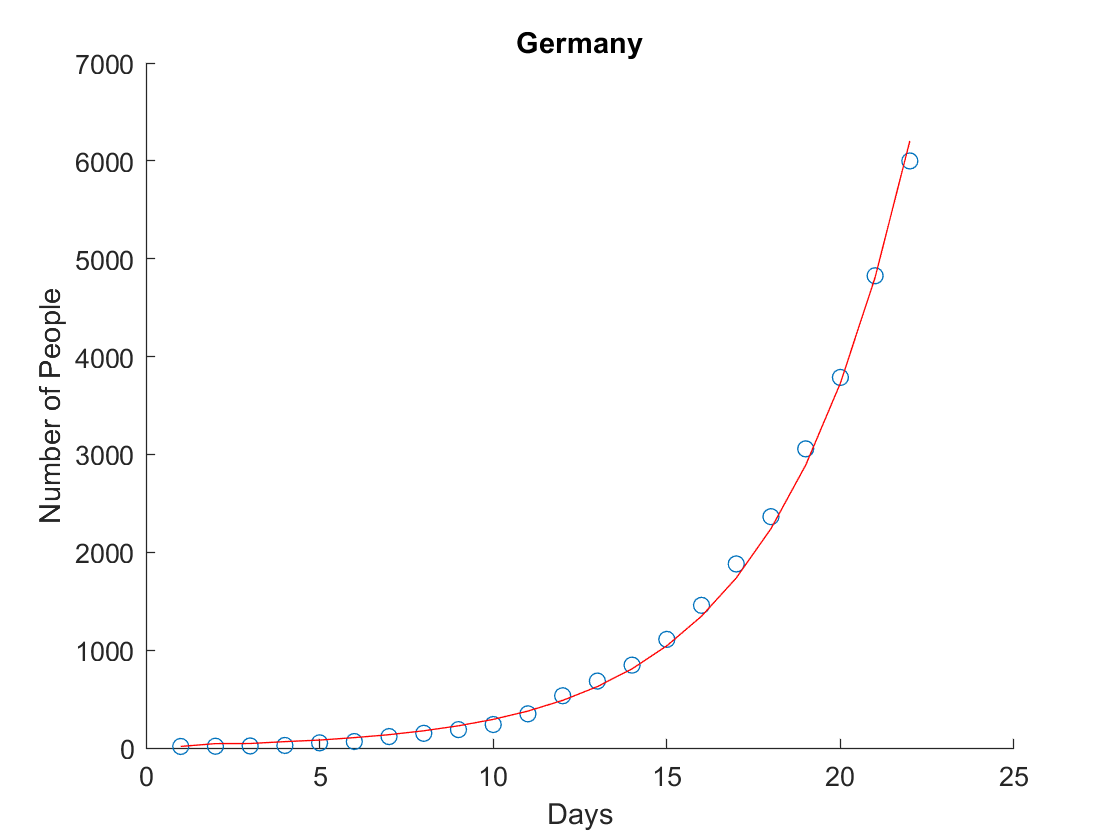


figure
scatter(1:length(infected), infected);
hold on
plot(1:length(sols), sols(3, :), 'r');
title('Canada')
xlabel('Days')
ylabel('Number of People')

function sols = numeric_sol(init_cond, params, population, delta_t, steps)
    %Euler's Method for numeric solutions to differential equations
    sols = zeros(4, steps);
    sols(1, 1) = init_cond(1); %S
    sols(2, 1) = init_cond(2); %E
    sols(3, 1) = init_cond(3); %I
    
    for x = 2:steps
        s = sols(1, x-1);
        e = sols(2, x-1);
        i = sols(3, x-1);
        sols(1, x) = sols(1, x-1) - delta_t*params(1)*i*s/population;
        sols(2, x) = sols(2, x-1) + delta_t*((params(1)*i*s)/population-params(3)*e);
        sols(3, x) = sols(3, x-1) + delta_t*(params(3)*e-params(2)*i);
    end
    sols(4,:) = population-sols(1,:)-sols(2,:)-sols(3,:); %R
end

function error = numeric_sol_err(params, infected, population)
    %comparing the predicted infected vs. actual infections
    %error is calculated through the squared difference 
    sols = numeric_sol([population-3*infected(1), 2*infected(1), infected(1), 0], params, population, 1, length(infected));
    error = sum((infected - sols(3, :)).^2, 'all');
end
